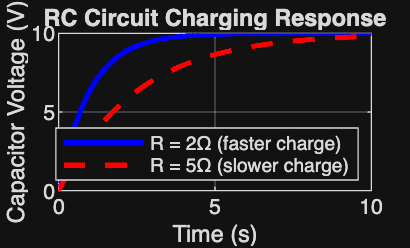

%{
ES115 - Control Panel Class Project
Author: Nivea Williamson
Version: 1.0
Date: 2026-04-19

Purpose:
    Simulate the voltage response of an RC circuit during charging
    and compare how different resistance values affect the response.

Input:
    - Voltage source (V)
    - Resistance values (R)
    - Capacitance (C)
    - Time step (dt)

Output:
    - Voltage vs time plot for RC circuit
    - Comparison of different resistance values

Engineering Algorithms:
    - Define time vector
    - Initialize capacitor voltage
    - Use time-stepping method to update voltage:
        Vc(n+1) = Vc(n) + (dt/RC)*(V - Vc(n))
    - Repeat for different R values
    - Plot results for comparison

MATLAB Tools/Functions:
    - for loop
    - plot()
    - hold on
    - grid on
    - legend()
%}

%% PROJECT 6: RC Circuit Simulation

clc;
clear;

% Parameters
V = 10;              % Supply voltage (Volts)
C = 0.5;             % Capacitance (Farads)
R1 = 2;              % Resistance 1 (Ohms)
R2 = 5;              % Resistance 2 (Ohms)

dt = 0.01;           % Time step
t = 0:dt:10;         % Time vector

% Initialize voltage arrays
Vc1 = zeros(size(t));
Vc2 = zeros(size(t));

%% Time-stepping simulation (Charging)

for i = 1:length(t)-1
    % Model 1
    Vc1(i+1) = Vc1(i) + (dt/(R1*C)) * (V - Vc1(i));
    
    % Model 2
    Vc2(i+1) = Vc2(i) + (dt/(R2*C)) * (V - Vc2(i));
end

%% Plot results
plot(t, Vc1, 'b', 'LineWidth', 2)
hold on;
plot(t, Vc2, 'r--', 'LineWidth', 2)

title('RC Circuit Charging Response')
xlabel('Time (s)')
ylabel('Capacitor Voltage (V)')
legend('R = 2Ω (faster charge)', 'R = 5Ω (slower charge)', 'Location', 'southeast')
grid on;

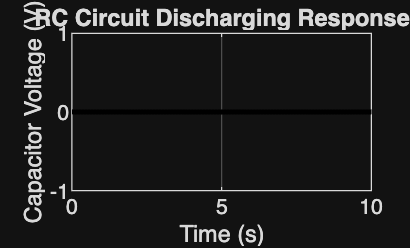


%% Optional: Discharging simulation
Vc_dis = Vc1;   % start from charged state

for i = 1:length(t)-1
    Vc_dis(i+1) = Vc_dis(i) - (dt/(R1*C)) * Vc_dis(i);
end

figure;
plot(t, Vc_dis, 'k', 'LineWidth', 2)
title('RC Circuit Discharging Response')
xlabel('Time (s)')
ylabel('Capacitor Voltage (V)')
grid on;